%传统方法 实验1

%标定
% Define images to process
imds=imageDatastore("10.17\标定");
imageFileNames=imds.Files

imageFileNames = 3×1 cell 数组
    {'C:\Users\12630\Desktop\图像处理\相机标定\10.17\标定\20241017-125524-114_f_50_d_0.554.bmp'}
    {'C:\Users\12630\Desktop\图像处理\相机标定\10.17\标定\20241017-125635-128_f_50_d_0.554.bmp'}
    {'C:\Users\12630\Desktop\图像处理\相机标定\10.17\标定\20241017-125648-418_f_50_d_0.554.bmp'}


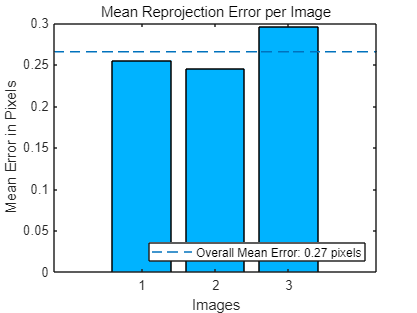

% images = imageDatastore(fullfile(toolboxdir("vision"), "visiondata", ...
%     "calibration", "mono"));
% imageFileNames = images.Files;
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames);
imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 1.500000e+00;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', true, 'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 3, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [],...
    "ImageSize",[mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

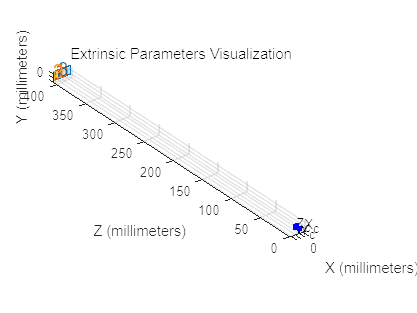


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [32286.0816 +/- 63115.347932253.2161 +/- 63045.9802]
Principal point (pixels):[ 1113.2246 +/- 95.6016     815.7205 +/- 130.2496]
Skew:                    [  -32.3616 +/- 47.3247 ]
Radial distortion:       [   -8.5129 +/- 33.3716 -1302.9398 +/- 10245.7244357056.4471 +/- 4217572.7797]
Tangential distortion:   [   -0.0750 +/- 0.1506       -0.0511 +/- 0.1052  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0030 +/- 0.0091        0.0094 +/- 0.0209        0.0032 +/- 0.0007  ]
                         [   -0.0034 +/- 0.0099        0.0142 +/- 0.0246       -0.0003 +/- 0.0007  ]
                         [    0.0026 +/- 0.0092       -0.0115 +/- 0.0239       -0.0059 +/- 0.0008  ]

Translation vectors (millimeters):
                         [  -10.6922 +/- 1.2015       -8.8009 +/- 1.6239      403.7830 +/- 789.2634]
          

%%验证重投影误差
%用cameraParams中给的重投影点计算误差
NumPatterns=cameraParams.NumPatterns;
ReprojectedPoints=cameraParams.ReprojectedPoints;
error=zeros(length(ReprojectedPoints),NumPatterns);
for i=1:NumPatterns
    for j=1:length(ReprojectedPoints)
        error(j,i)=norm(ReprojectedPoints(j,:,i)-imagePoints(j,:,i));
    end
end
MeanReprojectionError=mean(error)

MeanReprojectionError =     0.2879    0.2812    0.2908


%结论：与cameraParams中给的重投影误差值相符

%用world2img函数重新计算重投影点，再计算误差,注意要使用cameraParams中给的外参矩阵，而不是自己计算的外参矩阵
worldPoints3d=worldPoints;worldPoints3d(:,3)=0;%需要三维点，因此增加z轴坐标
error=zeros(length(ReprojectedPoints),NumPatterns);
for i=1:NumPatterns
    projectedPoints = world2img(worldPoints3d,cameraParams.PatternExtrinsics(i),cameraParams.Intrinsics,ApplyDistortion=true);
    for j=1:length(projectedPoints)
        error(j,i)=norm(projectedPoints(j,:)-imagePoints(j,:,i));
    end
end
MeanReprojectionError=mean(error)

MeanReprojectionError =     0.2879    0.2812    0.2908


%结论：与cameraParams中给的重投影误差值相符

%%计算平均校准精度 
% 计算过程先将失真点校正为未失真点
error=zeros(length(ReprojectedPoints),NumPatterns);
for i=1:NumPatterns
    undistortedPoints = undistortPoints(imagePoints(:,:,i),cameraParams);
    newWorldPoints= img2world2d(undistortedPoints,cameraParams.PatternExtrinsics(i),cameraParams.Intrinsics);
    for j=1:length(newWorldPoints)
        error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
    end
end
MeanCalibrationError=mean(error)

MeanCalibrationError =     0.0029    0.0028    0.0029


std(error)

ans =     0.0011    0.0012    0.0012



%对图像进行畸变校正后再提取角点坐标
error=zeros(length(ReprojectedPoints),NumPatterns);
for i=1:NumPatterns
    imOrig=imread(imageFileNames{i});
    [im, newOrigin] = undistortImage(imOrig, cameraParams);
    undistortedPoints = detectCheckerboardPoints(im);
    newWorldPoints= img2world2d(undistortedPoints,cameraParams.PatternExtrinsics(i),cameraParams.Intrinsics);
    for j=1:length(newWorldPoints)
        error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
    end
end
MeanCalibrationError=mean(error)

MeanCalibrationError =     0.0029    0.0029    0.0029


std(error)

ans =     0.0011    0.0011    0.0011


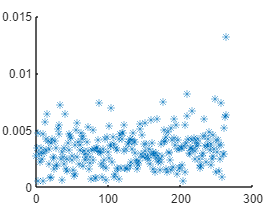

NumPoints=size(error,1)*size(error,2);
x=1:1:NumPoints;
scatter(x,reshape(error,[],1),"Marker","*")

error1=error;

RGB=imread(imageFileNames{3});
[im, newOrigin] = undistortImage(RGB, cameraParams);
[imagePoints, boardSize] = detectCheckerboardPoints(im);
camExtrinsics = estimateExtrinsics(imagePoints, worldPoints, cameraParams.Intrinsics);
%对所有实际标准块图像进行测量
imds=imageDatastore("10.17\测量(2)undis");
imageFileNames=imds.Files;
dists=zeros(length(imageFileNames),3);
for k=1:length(imageFileNames)    
    RGB=imread(imageFileNames{k});
    [RGB, newOrigin] = undistortImage(RGB, cameraParams);
    gray=rgb2gray(RGB);
    gray_edge=edge(gray,"canny",0.15);
    
    % 根据边缘特性，去除标准块内部的干扰边缘
    [row,col]=size(gray_edge);
    [P_left,P_right]=calculate_fitline(gray,gray_edge);
    
    y=linspace(1,row,5);
    x_r=(y-P_right(2))./P_right(1);
    x_l=(y-P_left(2))./P_left(1);
    for i=2:4
        [x_ver,y_ver]=find_vertical_ponit(P_right(1),P_right(2),x_l(i),y(i));
        imagePoints1 = [x_ver,y_ver;x_l(i),y(i)]+[newOrigin;newOrigin];
        worldPoints1 = img2world2d(imagePoints1, camExtrinsics,cameraParams.Intrinsics);
        dist2(i-1)=norm(worldPoints1(1,:)-worldPoints1(2,:));
    end
    dists(k,:)=dist2;
end
dists

dists =     2.9896    2.9899    2.9902
    2.9880    2.9883    2.9887
    2.9889    2.9892    2.9895
    2.9898    2.9901    2.9904
    2.9886    2.9889    2.9892
    4.9838    4.9844    4.9849
    4.9830    4.9835    4.9840
    4.9849    4.9855    4.9860
    4.9827    4.9833    4.9838
    4.9809    4.9814    4.9820


% dists=change_order(dists)

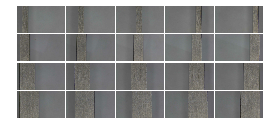

montage(imageFileNames,"Size",[4,5],"BorderSize",[5,5],"BackgroundColor",'w')

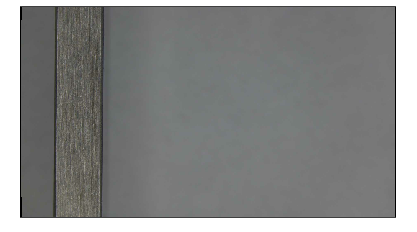


%对某一张标准块图像进行测量
RGB=imread("10.17\测量(2)undis\1.1undis.bmp");
[RGB, newOrigin] = undistortImage(RGB, cameraParams);
imshow(RGB)

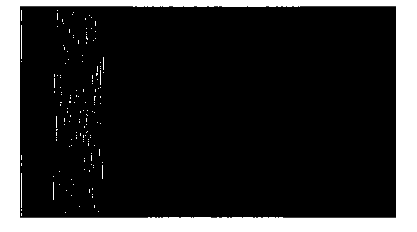

gray=rgb2gray(RGB);
gray_edge=edge(gray,"canny",0.3);
imshow(gray_edge)


% 根据边缘特性，去除标准块内部的干扰边缘
[row,col]=size(gray_edge);
edge_I=false(row,col);
n=60;
for i=n:row-n
    for j=n:col
        if gray_edge(i,j)==1
            edge_I(i,j)=1;
            break;
        end
    end
end
l_xy=subpixel_points2(gray,edge_I);
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';
% [P_left,l_xy_new]=polyfit_L(l_xy,5)
P_left=fit(l_xy(:,1),l_xy(:,2),ft,opts)

P_left =      线性模型 Poly1:
     P_left(x) = p1*x + p2
     系数(置信边界为 95%):
       p1 =      -110.9  (-111.6, -110.3)
       p2 =   2.375e+04  (2.361e+04, 2.388e+04)

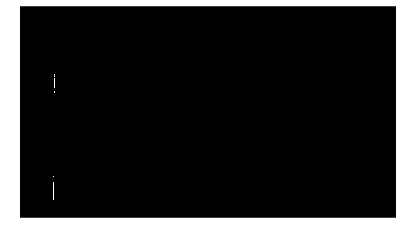

imshow(edge_I)

edge_I=false(row,col);
for i=n:row-n
    for j=col-n:-1:1
        if gray_edge(i,j)==1
            edge_I(i,j)=1;
            break;
        end
    end
end
r_xy=subpixel_points2(gray,edge_I);
% [P_right,xy_new]=polyfit_Para_L(r_xy,P_left(1),5)
P_right(1)=P_left.p1

P_right =  -110.9401  118.3297


P_right(2)=mean(r_xy(:,2)-P_right(1)*r_xy(:,1))

P_right = 1.0e+04 *

   -0.0111    5.6700


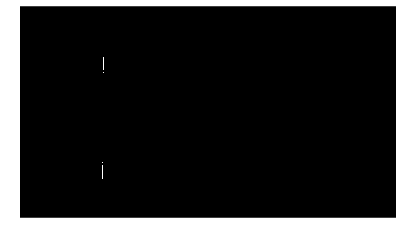

P_left=[P_left.p1,P_left.p2];
imshow(edge_I)

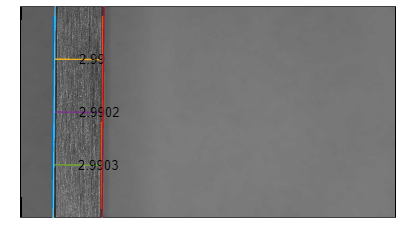

imshow(gray)
hold on
plot(l_xy(:,1),l_xy(:,2),".")
plot(r_xy(:,1),r_xy(:,2),".")
y=linspace(1,row,5);
x_r=(y-P_right(2))./P_right(1);
x_l=(y-P_left(2))./P_left(1);
for i=2:4
    [x_ver,y_ver]=find_vertical_ponit(P_right(1),P_right(2),x_l(i),y(i));
    plot([x_ver,x_l(i)],[y_ver,y(i)])
    imagePoints1 = [x_ver,y_ver;x_l(i),y(i)]+[newOrigin;newOrigin];
    worldPoints1 = img2world2d(imagePoints1, cameraParams.PatternExtrinsics(1),cameraParams.Intrinsics);
    dist2(i-1)=norm(worldPoints1(1,:)-worldPoints1(2,:));
    text(mean([x_ver,x_l(i)]),mean([y_ver,y(i)]),num2str(dist2(i-1)))
end
plot(x_l,y)
plot(x_r,y)
hold off

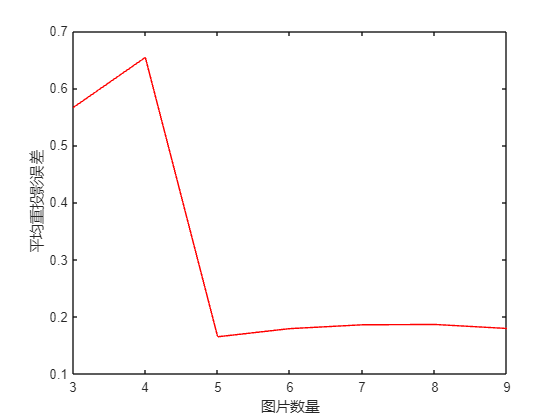

%图片数量对重投影误差的影响
NumPatterns=cameraParams.NumPatterns;
for i=3:NumPatterns
    [cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints(:,:,1:i), worldPoints, ...
    'EstimateSkew', true, 'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 3, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);
    error(i-2)=cameraParams.MeanReprojectionError;
end
x=3:NumPatterns;
plot(x,error,'r')
xlabel("图片数量")
ylabel("平均重投影误差")